# Homework 10

## [✔] ADSI Problem 6.2: Autocorrelation expression for an AR(1) process (proof)

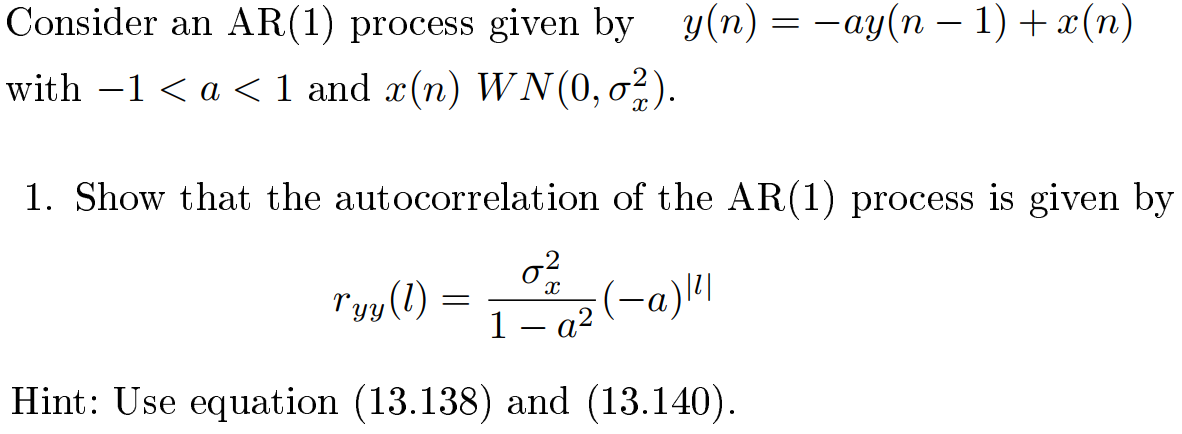

The autocorrelation of an AR(p) process is given by Eq. 13.138:

        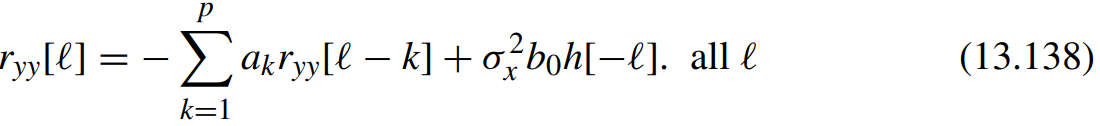

where $h\left\lbrack n\right\rbrack$ is the impulse response of an all-pole system.

Equation 13.138 is an general expression for all $\ell$. However, since $h\left\lbrack \ell \right\rbrack =0$ for negative values of $\ell$ then we know that $h\left\lbrack -\ell \right\rbrack =0$. Therefore, Eq. 13.138 can be reduced to:

        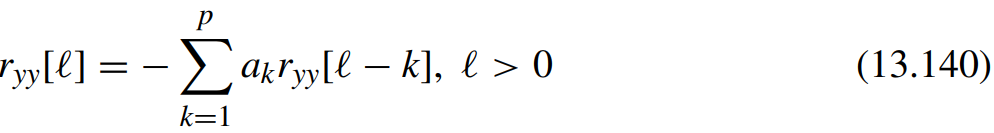

For an AR(1) process, Eq. 13.138 simplifies to:

        $r_{\mathrm{yy}} \left\lbrack \ell \right\rbrack =-a_1 r_{\mathrm{yy}} \left\lbrack \ell -1\right\rbrack +\sigma_x^2 b_0 h\left\lbrack -\ell \right\rbrack$ for all $\ell$

For an AR(1) process, Eq. 13.140 simplifies to:

        $r_{\mathrm{yy}} \left\lbrack \ell \right\rbrack =-a_1 r_{\mathrm{yy}} \left\lbrack \ell -1\right\rbrack$ for $\ell >0$

Setting $\ell =0$ in the first equation, we get:

        
$$r_{\textrm{yy}} \left\lbrack 0\right\rbrack =-a_1 r_{\textrm{yy}} \left\lbrack -1\right\rbrack +\sigma_x^2 b_0 h\left\lbrack 0\right\rbrack$$


The book says that $h\left\lbrack 0\right\rbrack =b_0 =1$ so we are left with:

        
$$r_{\textrm{yy}} \left\lbrack 0\right\rbrack =-a_1 r_{\textrm{yy}} \left\lbrack -1\right\rbrack +\sigma_x^2$$


We can use the symmetry property of autocorrelation function i.e., $r_{\mathrm{yy}} \left\lbrack -\ell \right\rbrack =r_{\mathrm{yy}} \left\lbrack -\ell \right\rbrack$:

        
$$r_{\textrm{yy}} \left\lbrack 0\right\rbrack =-a_1 r_{\textrm{yy}} \left\lbrack 1\right\rbrack +\sigma_x^2$$


To find an expression for $r_{\mathrm{yy}} \left\lbrack 1\right\rbrack$, we set $\ell =1$ in the second equation:

        
$$r_{\textrm{yy}} \left\lbrack 1\right\rbrack =-a_1 r_{\textrm{yy}} \left\lbrack 0\right\rbrack$$


We insert the second equation into the first equation:

        
$$r_{\textrm{yy}} \left\lbrack 0\right\rbrack =-a_1 \left(-a_1 r_{\textrm{yy}} \left\lbrack 0\right\rbrack \right)+\sigma_x^2$$


        
$$r_{\textrm{yy}} \left\lbrack 0\right\rbrack =a_1^2 r_{\mathrm{yy}} \left\lbrack 0\right\rbrack +\sigma_x^2$$


        
$$\sigma_x^2 =r_{\textrm{yy}} \left\lbrack 0\right\rbrack -a_1^2 r_{\textrm{yy}} \left\lbrack 0\right\rbrack$$


        
$$\sigma_x^2 =r_{\textrm{yy}} \left\lbrack 0\right\rbrack \left(1-a_1^2 \right)$$


        
$$r_{\textrm{yy}} \left\lbrack 0\right\rbrack =\frac{\sigma_x^2 }{1-a_1^2 }$$


Now, we need to find an expression for $\ell >0$. We can do this by using the second equation.

First, we set $\ell =1$ in the second equation:

        
$$r_{\textrm{yy}} \left\lbrack 1\right\rbrack =-a_1 r_{\textrm{yy}} \left\lbrack 0\right\rbrack \Leftrightarrow -a_1 \frac{\sigma_x^2 }{1-a_1^2 }$$


        
$$r_{\textrm{yy}} \left\lbrack 2\right\rbrack =-a_1 r_{\textrm{yy}} \left\lbrack 1\right\rbrack \Leftrightarrow -a_1 \left(-a_1 \frac{\sigma_x^2 }{1-a_1^2 }\right)\Leftrightarrow {\left(-a_1 \right)}^2 \frac{\sigma_x^2 }{1-a_1^2 }$$


        
$$r_{\textrm{yy}} \left\lbrack 3\right\rbrack =-a_1 r_{\textrm{yy}} \left\lbrack 2\right\rbrack \Leftrightarrow -a_1 \left({\left(-a_1 \right)}^2 \frac{\sigma_x^2 }{1-a_1^2 }\right)\Leftrightarrow {\left(-a_1 \right)}^3 \frac{\sigma_x^2 }{1-a_1^2 }$$


This means that in general, we have:

        
$$r_{\textrm{yy}} \left\lbrack \ell \right\rbrack ={\left(-a_1 \right)}^{\ell } \frac{\sigma_x^2 }{1-a_1^2 }$$


If we apply the symmetric property of the autocorrelation, we get:

        
$$r_{\textrm{yy}} \left\lbrack \ell \right\rbrack ={\left(-a_1 \right)}^{\left|\ell \right|} \frac{\sigma_x^2 }{1-a_1^2 }$$


## ADSI Problem 6.3: Wiener FIR Filtering, minimum square error

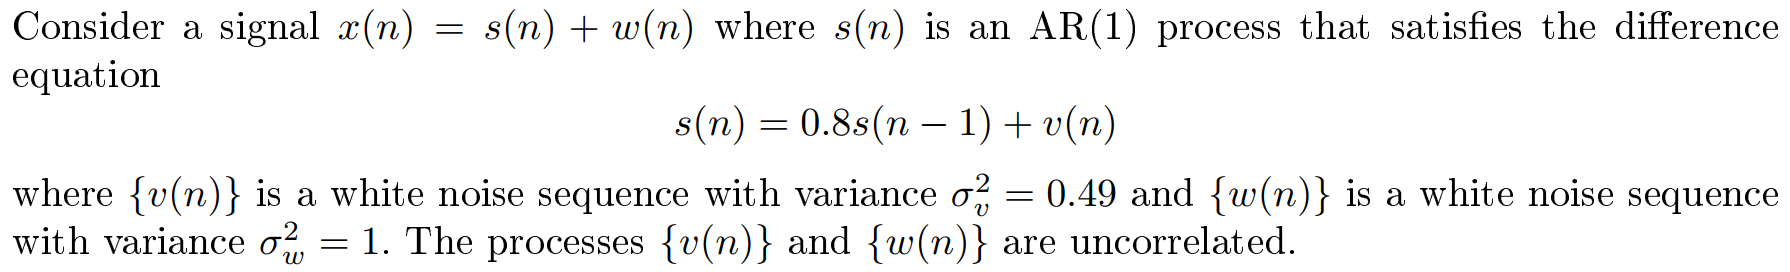

        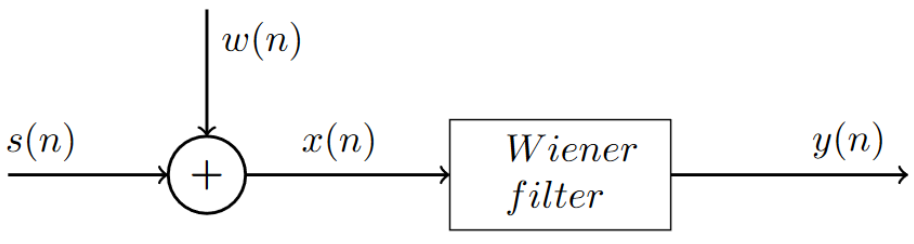

clear variables;

### [✔] 1) Determine the autocorrelation sequence for a signal with two noise processes

In Problem 6.2, we found that the autocorrelation function of an AR(1) is:

        
$$r_{\mathrm{yy}}^{\mathrm{AR}\left(1\right)} \left(\ell \right)={\left(-a_1 \right)}^{\left|\ell \right|} \frac{\sigma_x^2 }{1-a_1^2 }$$


For the AR(1) process, we are given $a_1 =-0\ldotp 8$ and $\sigma_v^2 =0\ldotp 49$. So the autocorrelation sequence for $s\left(n\right)$ is:

        
$$r_{\mathrm{ss}} \left(\ell \right)={0\ldotp 8}^{\left|\ell \right|} \frac{0\ldotp 49}{1-{\left(-0\ldotp 8\right)}^2 }={0\ldotp 8}^{\left|\ell \right|} \frac{0\ldotp 49}{0\ldotp 36}$$


Next, we need to find the autucorrelation sequence for $w\left(n\right)$. The autocorrelation of white Gaussian noise is $\sigma_w^2 \delta \left(\ell \right)$ so since white noise has unit variance i.e. $\sigma_w^2 =1$ we have:

        
$$r_{\mathrm{ww}} \left(\ell \right)=\delta \left(\ell \right)$$


Since the two noise processes are uncorrelated, the ACRS of $\left\lbrace x\left(n\right)\right\rbrace$ process is:

        
$$r_{\mathrm{xx}} \left(\ell \right)={0\ldotp 8}^{\left|\ell \right|} \frac{0\ldotp 49}{0\ldotp 36}+\delta \left(\ell \right)$$


### [👀] 2) Design a Wiener filter of length M=2 to estimate an AR(1) process

The optimum Wiener filter to estimate a random process is given by Eq. 14.109:

        

where ${\mathit{\mathbf{R}}}_x$ is the correlation matrix of a random vector $\mathit{\mathbf{x}}$ and $\mathit{\mathbf{g}}$ is the cross-correlation vector between $\mathit{\mathbf{x}}$ and $y$ (the signal that we want to recover which in this problem is $s\left\lbrack n\right\rbrack$). 

Basically, to design a $p$th order Wiener filter, we have to solve following equation with respect to $\mathit{\mathbf{h}}$:

        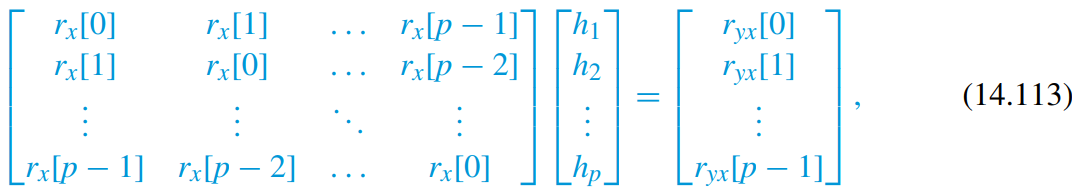

Computing the autocorrelation matrix is straightforward since we have computed the autocorrelation $r_{\textrm{xx}} \left(\ell \right)$ in part 1).

M = 2;
ell = 0:M-1;

r_ss = 0.8.^abs(ell) * (0.49/0.36);
r_ww = (ell == 0); % Simulate the delta function
r_xx = r_ss + r_ww;
R_xx = toeplitz(r_xx)

R_xx =     2.3611    1.0889
    1.0889    2.3611


We have to come up with an expression for the cross-correlation $r_{\textrm{sx}} \left(\ell \right)$:

        
$$r_{\mathrm{sx}} \left(\ell \right)=E\left\lbrack s\left(n\right)x\left(n-\ell \right)\right\rbrack$$


        
$$r_{\textrm{sx}} \left(\ell \right)=E\left\lbrack s\left(n\right)\left(s\left(n-\ell \right)+w\left(n-\ell \right)\right)\right\rbrack$$


        
$$r_{\textrm{sx}} \left(\ell \right)=E\left\lbrack s\left(n\right)s\left(n-\ell \right)+s\left(n\right)w\left(n-\ell \right)\right\rbrack$$


        
$$r_{\textrm{sx}} \left(\ell \right)=E\left\lbrack s\left(n\right)s\left(n-\ell \right)\right\rbrack +E\left\lbrack s\left(n\right)w\left(n-\ell \right)\right\rbrack$$


Since the processes $s\left(n\right)$ and $w\left(n\right)$ are uncorrelated:

        
$$r_{\textrm{sx}} \left(\ell \right)=E\left\lbrack s\left(n\right)s\left(n-\ell \right)\right\rbrack +E\left\lbrack s\left(n\right)\right\rbrack \cdot E\left\lbrack w\left(n-\ell \right)\right\rbrack$$


👀 ***Is it okay to make this assumption?***

We assume that $w\left(n\right)$ is a zero-mean WGN, we know that $E\left\lbrack w\left(n\right)\right\rbrack =0$, so we are left with

        
$$r_{\textrm{sx}} \left(\ell \right)=r_{\mathrm{ss}} \left(\ell \right)+0$$


From 1), we know the that:

        
$$r_{\textrm{ss}} \left(\ell \right)={0\ldotp 8}^{\left|\ell \right|} \frac{0\ldotp 49}{0\ldotp 36}$$


g = r_ss';

h_opt = R_xx\g % Same as `inv(R_xx)*g` but better

h_opt =     0.4621
    0.2481


### [✔] 3) Determine the minimum mean square error for M=2

The minimum square error for an optimum $p$th Wiener (FIR) filter is given by Eq. 14.115:

        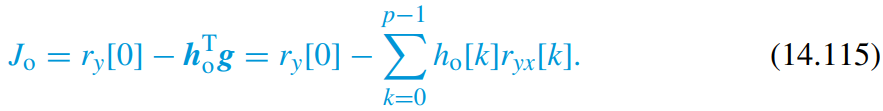

mse = r_ss(1) - h_opt'*g

mse = 0.4621

## [»] ADSI Problem 6.4: Linear interpolation, estimate missing samples

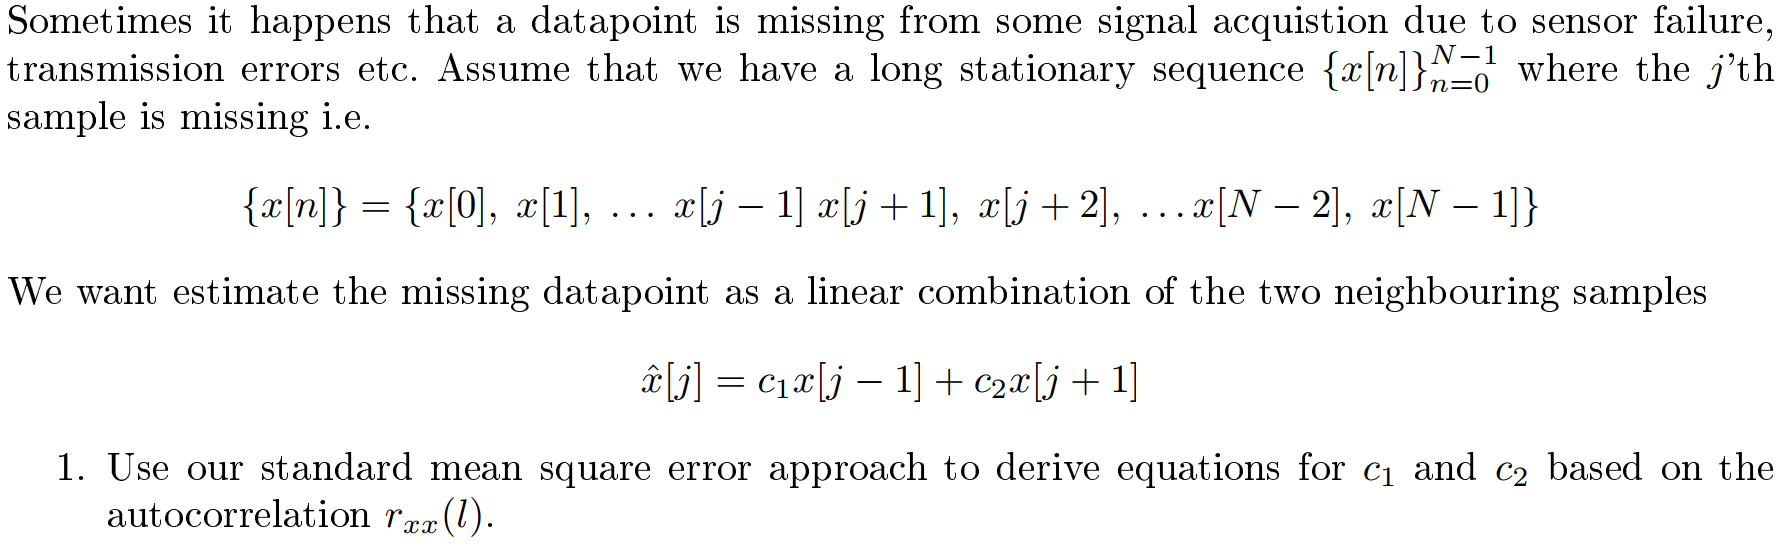

### 1) Use mean squared error to derive coefficients based on the ACRS

We want to estimate a missing sample $x\left(j\right)$ as a linar combination of two neighbouring samples:

        
$$\hat{x} \left(j\right)=c_1 x\left(j-1\right)+c_2 x\left(j+1\right)$$


To find the coefficients $c_1$ and $c_2$ using the mean squared error method, we need to take following steps:

- Find an expression for the error: $e\left(n\right)$

- Square the error quantity: $e^2 \left(n\right)$

- Take the expectation of squared error: $E\left\lbrack e^2 \left(n\right)\right\rbrack$

- Take the partial derivatives of expectation with respect to each of the coefficients

- Set the derivatives to zero and solve them

Step 1: The error of the estimate is:

        
$$e\left(j\right)=x\left(j\right)-\hat{x} \left(j\right)$$


        
$$e\left(j\right)=x\left(j\right)-\left(c_1 x\left(j-1\right)+c_2 x\left(j+1\right)\right)$$


        
$$e\left(j\right)=x\left(j\right)-c_1 x\left(j-1\right)-c_2 x\left(j+1\right)$$


Step 2: square the error

        
$$e^2 \left(j\right)=\left(x\left(j\right)-c_1 x\left(j-1\right)-c_2 x\left(j+1\right)\right)\left(x\left(j\right)-c_1 x\left(j-1\right)-c_2 x\left(j+1\right)\right)$$


syms c1 c2 x_j x_jm1 x_jp1
expand((x_j - c1*x_jm1 - c2*x_jp1)^2)

$$ans = {c_{1}}^{2}\,{x_{\mathrm{jm1}}}^{2}+2\,c_{1}\,c_{2}\,x_{\mathrm{jm1}}\,x_{\mathrm{jp1}}-2\,c_{1}\,x_{j}\,x_{\mathrm{jm1}}+{c_{2}}^{2}\,{x_{\mathrm{jp1}}}^{2}-2\,c_{2}\,x_{j}\,x_{\mathrm{jp1}}+{x_{j}}^{2}$$

        
$$e^2 \left(j\right)=c_1^2 x^2 \left(j-1\right)+2c_1 c_2 x\left(j-1\right)x\left(j+1\right)-2c_1 x\left(j\right)x\left(j-1\right)+c_2^2 x^2 \left(j+1\right)-2c_2 x\left(j\right)x\left(j+1\right)+x^2 \left(j\right)$$


Step 3: Take the expectation of the squared error:

        
$$E\left\lbrack e^2 \left(j\right)\right\rbrack =E\left\lbrack c_1^2 x^2 \left(j-1\right)+2c_1 c_2 x\left(j-1\right)x\left(j+1\right)-2c_1 x\left(j\right)x\left(j-1\right)+c_2^2 x^2 \left(j+1\right)-2c_2 x\left(j\right)x\left(j+1\right)+x^2 \left(j\right)\right\rbrack$$


        
$$E\left\lbrack e^2 \left(j\right)\right\rbrack =c_1^2 E\left\lbrack x^2 \left(j-1\right)\right\rbrack +2c_1 c_2 E\left\lbrack x\left(j-1\right)x\left(j+1\right)\right\rbrack -2c_1 E\left\lbrack x\left(j\right)x\left(j-l\right)\right\rbrack$$


                          
$$+c_2^2 E\left\lbrack x^2 \left(j+1\right)\right\rbrack -2c_2 E\left\lbrack x\left(j\right)x\left(j+1\right)\right\rbrack +E\left\lbrack x^2 \left(j\right)\right\rbrack$$


From the expression, we observe different autocorrelation values:

        
$$E\left\lbrack e^2 \left(j\right)\right\rbrack =c_1^2 r_{\mathrm{xx}} \left(1\right)+\ldotp \ldotp \ldotp \ldotp$$


Finish it up...

## [»] ADSI Problem 6.5: Levinson-Durbin by Hand

*The aim of this problem is to get a finger-tip feeling of the flow of the Levinson-Durbin recursion. Assume that the following autocorrelation function values have been determined from an unknown random process  *$\left\lbrace x\left(n\right)\right\rbrace$

        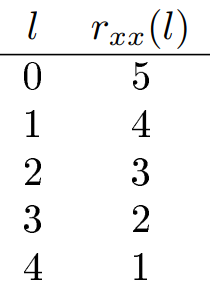

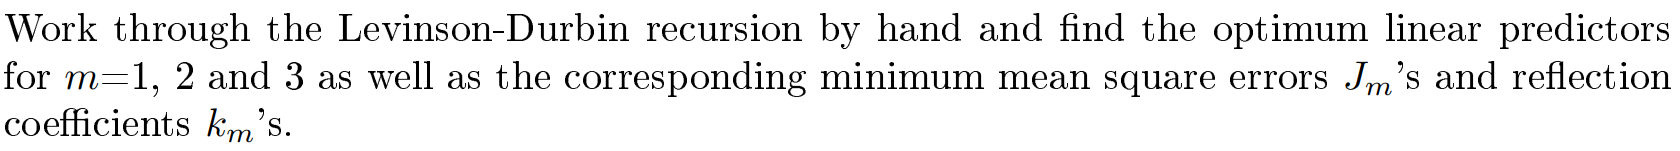

### 1) Work though Levinson-Durbin by hand to find the optimum linear predictors for m=1,2,3

### 2) Find the corresponding minimum mean square errors

### 3) Find the corresponding reflection coefficients

## [✔] ADSI Problem 6.6: Levinson-Durbin and linear prediction

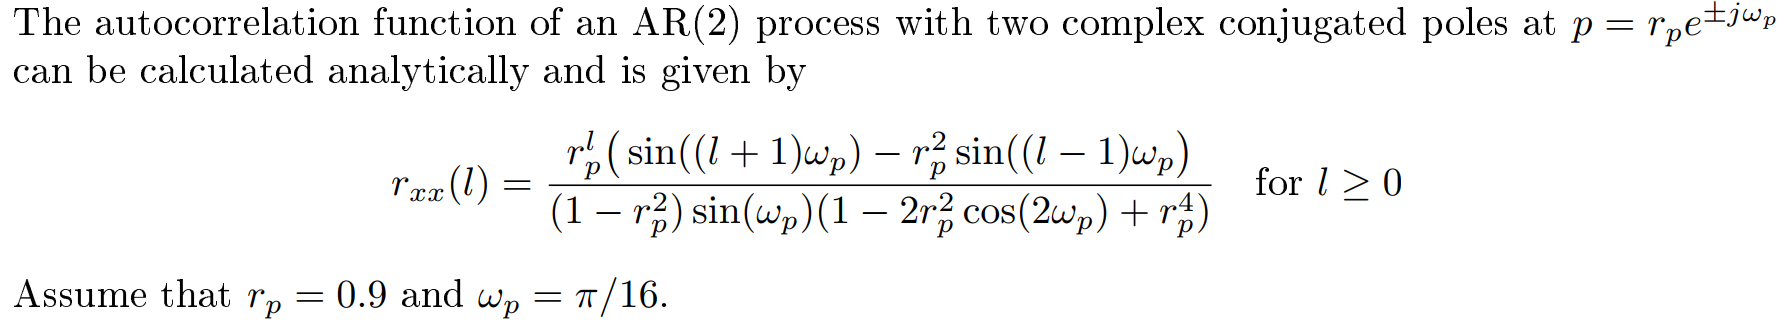

### [✔] 1) Plot the autocorrelation function.

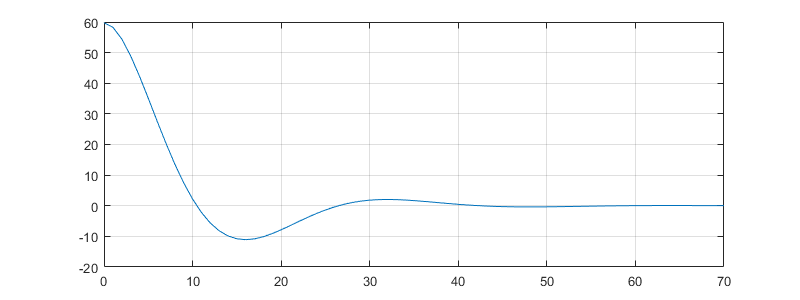

rp = 0.9;
wp = pi/16;

l = 0:70;

nominator = rp.^l.* (sin((l + 1)*wp) - rp^2*sin((l - 1)*wp));
denominator = (1 - rp^2) * sin(wp) * (1 - 2*rp^2*cos(2*wp) + rp^4);
r_xx = nominator / denominator;

figure('position', [0, 0, 800, 300])
plot(l, r_xx)
grid on;

### [✔] 2) Compute reflection coefficients for m'th order optimum linear predictors

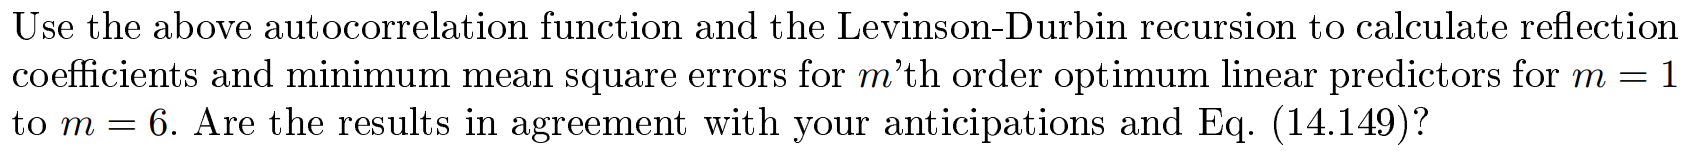

First, we use the MATLAB function `levinson(r_xx, m)` to compute the reflection coefficients and the corresponding errors for the different $m$'th order linear predictors:

M = 6;
err = zeros(M, 1); % Array to store the errors

for m=1:M
    [a, e, k] = levinson(r_xx, m);
    % `a` is the coefficients of the AR(m) model
    % `e` is the prediction error of m'th order optimimum linear predictor
    % `k` is the reflection coefficients of the linear predictor    
    err(m) = e;
    display(strcat('Coefficients for a', 32, num2str(m), '-th order predictor', 32))
    display(k)
end

Coefficients for a 1-th order predictor 


k = -0.9754

Coefficients for a 2-th order predictor 


k =    -0.9754
    0.8100


Coefficients for a 3-th order predictor 


k =    -0.9754
    0.8100
   -0.0000


Coefficients for a 4-th order predictor 


k =    -0.9754
    0.8100
   -0.0000
   -0.0000


Coefficients for a 5-th order predictor 


k =    -0.9754
    0.8100
   -0.0000
   -0.0000
    0.0000


Coefficients for a 6-th order predictor 


k =    -0.9754
    0.8100
   -0.0000
   -0.0000
    0.0000
   -0.0000


It is important to note that the reflection coefficients $\left\lbrace k_3 ,k_4 ,k_5 ,k_6 \right\rbrace$ are zero. This is to be expected as the reflection coefficients is dependent on the AR(q) model. Since we have an AR(2) model, the corresponding reflection coefficients become zero.

Let us consider the error of each of the predictors. Eq. 14.149 states that the prediction error can be calculated based on the previous error and current reflection coefficient:

        

where $J_0 =r_{\mathrm{xx}} \left(0\right)$ and $\beta_1 =r_{\mathrm{xx}} \left(1\right)$

The squared error should be 1 once the order of the predictor matches or exceeds the AR(q) model.

J0 = r_xx(1)

J0 = 59.7579

J1 = (1 - k(1)^2) * J0

J1 = 2.9078

J2 = (1 - k(2)^2) * J1

J2 = 1.0000

J3 = (1 - k(3)^2) * J2

J3 = 1.0000

Let us plot the order of the linear predictor versus the prediction error for an AR(2) model.

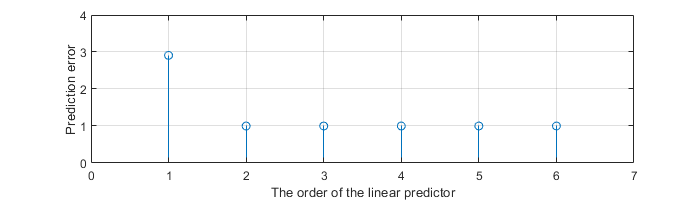

figure('position', [0, 0, 700, 200])
stem(err)
xlabel('The order of the linear predictor')
ylabel('Prediction error')
xlim([0, M+1])
ylim([0, 4])
grid on;

## ADSI Problem 6.7: Linear prediction

This problem addresses linear prediction on a simple harmonic signal where the results can be compared with our intuitive understanding.  

        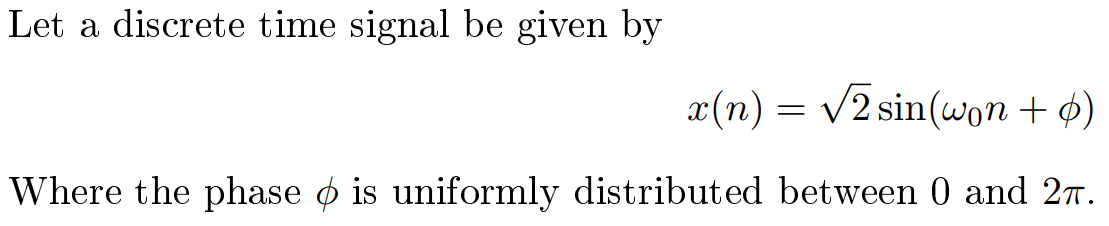

### 1) Determine the autocorrelation function for *x*(*n*)

### 2) Determine the 2nd order forward linear prediction filter

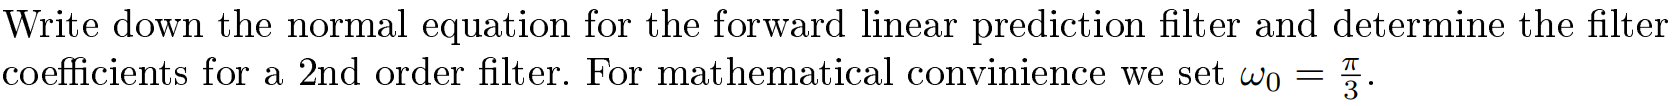

### 3) Find the system function for the filter and locate the zeros

### 4) Determine the frequency response, plot it and comment on the result

### 5) Calculate the prediction error

## ADSI Problem 6.8: Autocorrelation function and linear prediction

*Assume that for a given sequence of data *$\left\lbrace x\left(n\right)\right\rbrace$* the autocorrelation function has been calculated and used to solve the normal equations so that the optimum p'th order linear predictor was found. Now, an amplifier is placed in the signal chain so that the signal is *$\left\lbrace c\cdot x\left(n\right)\right\rbrace$*. How does the autocorrelation function and the linear predictor change?*

# Functions